% Experiment on the Cascaded watertanks benchmark
%
% References
% ---------
%
% A Tensor Network Kalman filter with an application in recursive MIMO Volterra system identification
% 2016, Kim Batselier, Zhongming Chen, Ngai Wong
% 


clear all
close all
clc

%for reproducibility
rng(1);

load('dataBenchmark')

Preprocessing Data

tic

% Normalize the input and output training data to [0 1]
input = uEst/7;
output = yEst/10-0.1;

% plot(input)
% plot(output)
% 
% histogram(input)
% histogram(output)

% Normalize the input and output test data to [0 1]
tinput = uVal/7 ;
toutput = yVal/10-0.1;

% Choose the lags for the input and output
inlags=[1 2];
outlags=[0 1 2 4 8 12 16];

ending = 1024-outlags(end)-1;

% generate features using input lags
for l = 1:length(inlags)
u(:,l) = input(end-inlags(l)-ending:end-inlags(l));
uv(:,l) = tinput(end-inlags(l)-ending:end-inlags(l));
end
% generate features using output lags
for l = 1:length(outlags)
y(:,l) = output(end-outlags(l)-ending:end-outlags(l));
yv(:,l) = toutput(end-outlags(l)-ending:end-outlags(l));
end



Split test and training set

% Features are lagged inputs and outputs
featurez = [y(:,end:-1:2)  u];
% Target is output with zero lag
zeta = y(:,1);

tfeaturez = [yv(:,end:-1:2)  uv];
yt = yv(:,1);



Construct B-spline basis vectors


[N, d]=size(featurez); % Number of samples and features

n = 3;                  %Degree B-spline
m = 1;                  %Number of knot intervals
In = n+m;               %Number of B-splines

% Construct the basis vectors from the features
un = basisvectors(featurez,n,m);



Initialize tensor train

% Choose TT-ranks
maxrank = 3;
r = (min(min(In.^[0:d],In.^[d:-1:0]),maxrank));

% Initialize Tensor Train and Vp and Vm
[TN,Vm,Vp] = initTT(un,r,d);


Show storage compression ratio


Pcount = (In)^d;                    %Original tensor size
dof = sum(prod(TN.sz,2));           %TT storage size.
disp(['Compression: ' num2str(dof/Pcount)])  %compression ratio

Compression: 0.0036621


Optimize TT cores

% rez = [];

lambda=2*10^-4 ;
% lambda=1;
gamma=0;

e=10^-5;

difforder=2;
MAXITR = 20;
MAXRANK = 6;
% MAXITR = 100;
Tes = 0

Tes = 0

% nselect = floor(logspace(log10(dof/N),0,MAXITR)*0.5*N);


% MAXITR = d;
nselect = ones([1,MAXITR])*N;
% plot(nselect)

% [TN,Vm,Vp,res1,res2] = optimTT(TN,Vm,Vp,un,zeta,MAXITR,nselect,lambda,gamma,difforder);
% [TN,Vm,Vp,res1,res2] = optimTTmals(TN,Vm,Vp,un,zeta,MAXITR,nselect,lambda,gamma,difforder)
% rez = [rez res1];


% 
% res1=[];
% res2=[];
% itr=1;                          % counts number of iterations
% ltr=1;                          % flag that checks whether we sweep left to right
% sweepindex=1;                   % index that indicates which TT core will be updated
% 
% [N, ~]=size(un{1}); 
% d=size(TN.sz,(1)); 
% I = TN.sz(:,2);
% r = [TN.sz(:,1);1];
% P = diff(eye(I(1)),difforder);
% PP = P'*P;
% 
% tic
% while (itr <= MAXITR )
% %     ---------------------updateTT-----------------;
%         %Select random batch of data
%         dataselect = randperm((N),nselect(itr));  
%         
%         %Construct regressor A
%          
%         %Construct difference penalty matrices
% %         W = penalmat(TN,sweepindex,d,P,PP);
% %         
% %         %Sum the difference penalty matrices to penalize each dimension equally
% %         WWW = W{1};
% %         for s =2:d
% %             WWW = WWW + W{s};
% %         end
%           
%         %Solve linear subsystem 
% 
%              g=pinv(A'*A + lambda*eye(size(A'*A)))*(A'*zeta(dataselect,:));
% 
%         %Update cores
%        
%                 if ltr
% %             left-to-right sweep, generate left orthogonal cores and update Vm
%                             
%             [U,S,V] = svd(reshape(g,[r(sweepindex)*(I(sweepindex)),r(sweepindex+1)]));
%             
%             sings = diag(S);
%             cumuls = cumsum(sings)/sum(sings);
%             
%             delta = (e/(sqrt(d-1)));
%             tempR = r(sweepindex+1);
%             r(sweepindex+1) = min(find(cumuls>1-delta, 1), MAXRANK);
%             
%             Utrun = U(:,1:r(sweepindex+1));
%             Strun = S(1:r(sweepindex+1),1:r(sweepindex+1));
%             Vtrun = V(:,1:r(sweepindex+1));
%             Q = Utrun; R = Strun*Vtrun';
%             TN.core{sweepindex}=reshape(Q(:,1:r(sweepindex+1)),[r(sweepindex),I(sweepindex),r(sweepindex+1)]);
%             TN.core{sweepindex+1}=reshape(R(1:r(sweepindex+1),:)*reshape(TN.core{sweepindex+1},[tempR,(I(sweepindex+1))*r(sweepindex+2)]),[r(sweepindex+1),I(sweepindex+1),r(sweepindex+2)]);
%             Vm{sweepindex+1}=dotkron(Vm{sweepindex},un{sweepindex})*reshape(TN.core{sweepindex},[r(sweepindex)*I(sweepindex),r(sweepindex+1)]); 
%         else
% %             right-to-left sweep, generate right orthogonal cores and update Vp
%             [Q,R]=qr(reshape(g,[r(sweepindex),(I(sweepindex))*r(sweepindex+1)])'); 
%             TN.core{sweepindex}=reshape(Q(:,1:r(sweepindex))',[r(sweepindex),I(sweepindex),r(sweepindex+1)]);
%             TN.core{sweepindex-1}=reshape(reshape(TN.core{sweepindex-1},[r(sweepindex-1)*(I(sweepindex-1)),r(sweepindex)])*R(1:r(sweepindex),:)',[r(sweepindex-1),I(sweepindex-1),r(sweepindex)]);
%             Vp{sweepindex-1}=dotkron(Vp{sweepindex},un{sweepindex})*reshape(permute(TN.core{sweepindex},[3 2 1]),[r(sweepindex+1)*I(sweepindex),r(sweepindex)]);  
%         end
%        
%     
%         %Update sweep
%      
%                 if ltr
%                     sweepindex=sweepindex+1;
%                     if sweepindex== d                
%                         ltr=0;
%                         timer=toc;
%                     end
%                 else
%                     sweepindex=sweepindex-1;
%                     if sweepindex== 1                
%                         ltr=1;
%                         timer=toc;
%                     end
%                 end
%     
%     
%         % only check residual after 1 half sweep
%         if (sweepindex==d) || (sweepindex==1) % half a sweep
%             
%             res1(itr)=norm(A*g-zeta(dataselect,:))^2/(nselect(itr)); % check residual
%             res2(itr)=lambda*(g'*g);
% 
%             disp(["iteration:" itr timer])
% %              disp(sweepindex)
%             itr=itr+1; %update iteration
%         end   
% end  
% 


res1=[];
res2=[];
itr=1;                          % counts number of iterations
ltr=1;                          % flag that checks whether we sweep left to right
sweepindex=1;                   % index that indicates which TT core will be updated

[N, ~]=size(un{1}); 
d=size(TN.sz,(1)); 
I = TN.sz(:,2);
r = [TN.sz(:,1);1];
P = diff(eye(I(1)),difforder);
PP = P'*P;


ans =      1     3     3     3     3     3     3     3     1


tic
while (itr <= MAXITR )
%     ---------------------updateTT-----------------;
        saveR(itr,:) = r;        

        %Select random batch of data
        dataselect = randperm((N),nselect(itr));  
        
        %Construct regressor A
%         A=dotkron(Vm{sweepindex}(dataselect,:),un{sweepindex}(dataselect,:),Vp{sweepindex}(dataselect,:));
        
        A=dotkron(Vm{sweepindex}(dataselect,:), dotkron(un{sweepindex}(dataselect,:), dotkron(un{sweepindex+1}(dataselect,:), Vp{sweepindex+1}(dataselect,:))));
        

%           %Construct difference penalty matrices
%         W = penalmat(TN,sweepindex,d,P,PP);

% ---------------------------------------------------------------------------
        for j=1:d
        Csize = TN.sz(j,:);
        
        Dm = reshape(permute(TN.core{j}, [2 1 3]), [Csize(2) Csize(1)*Csize(3)]);
        mDDm = reshape(Dm'*Dm, [Csize(1) Csize(3) Csize(1) Csize(3)]);                      %O(I*r^4)
        DD{j} = reshape(permute(mDDm,[1 3 2 4]), [Csize(1)*Csize(1) Csize(3)*Csize(3)]);
        PD = P*Dm;                                                                          %O(I^2*r^2)
        DPPD = reshape(PD'*PD, [Csize(1) Csize(3) Csize(1) Csize(3)]);                      %O(I^2*r^4)
        DWD{j} = reshape(permute(DPPD,[1 3 2 4]), [Csize(1)*Csize(1) Csize(3)*Csize(3)]);   
        eyez{j}= reshape(eye(Csize(1)), [Csize(1)^2 1]);                    
        eyep{j}= reshape(eye(Csize(2)), [Csize(2)^2 1]);                    
        end
        eyez{d+1}=1;
        
        for p= 1:d   %O(d^2*r^4)   
                if sweepindex==p
                    D1 = eyez{sweepindex};
                    D2 = PP(:);
                    D3 = eyep{sweepindex+1};
                    D4 = eyez{sweepindex+2};
                elseif (sweepindex+1)==p
                    D1 = eyez{sweepindex};
                    D2 = eyep{sweepindex};
                    D3 = PP(:);                    
                    D4 = eyez{sweepindex+2};
                elseif (sweepindex+1)<p
                    D1 = eyez{sweepindex};  
                    D2 = eyep{sweepindex}; 
                    D3 = eyep{sweepindex+1};
                    D4= DWD{p}*eyez{p+1};           
                    for it=(p-1):-1:(sweepindex+2)               
                        D4 = DD{it}*D4;                     %O(d*r^4)
                    end                               
                elseif sweepindex>p   
                    D1= eyez{p}'*DWD{p};
       
                    for it=(p+1):(sweepindex-1)               
                        D1 = D1*DD{it};                     %O(d*r^4)
                    end
                    D1=D1';
                    D2 = eyep{sweepindex}; 
                    D3 = eyep{sweepindex+1};
                    D4= eyez{sweepindex+2}; 
                end
            Dsz(1) = TN.sz(sweepindex,1);
            Dsz(2) = TN.sz(sweepindex,2);
            Dsz(3) = TN.sz(sweepindex+1,2);
            Dsz(4) = TN.sz(sweepindex+1,3);
            
            WW = kron(D4,kron(D3, kron(D2, D1))); %O(I^4*r^4)
            Wtemp = permute(reshape(WW, [Dsz(1) Dsz(1) Dsz(2) Dsz(2) Dsz(3) Dsz(3) Dsz(4) Dsz(4)]), [1 3 5 7 2 4 6 8]);
            W{p} = reshape(Wtemp, [prod(Dsz) prod(Dsz)]); 
        end

% ---------------------------------------------------------------------------
        WWW = W{1};
        for s =2:d
            WWW = WWW + W{s};
        end
        
        WWW = round(WWW);
        
        %Solve linear subsystem 

             g=pinv(A'*A + lambda*WWW)*(A'*zeta(dataselect,:));
%              g=pinv(A'*A + lambda*eye(size(A'*A)))*(A'*zeta(dataselect,:));

        %Update cores
            
            C = reshape(g,[r(sweepindex)*(I(sweepindex)),I(sweepindex+1)*r(sweepindex+2)]);       
            [U,S,V] = svd(C);
            
            sings = diag(S);
            cumuls = cumsum(sings)/sum(sings);
            
            delta = (e/(sqrt(d-1)));
%             r(sweepindex+1) = min(find(cumuls>1-delta, 1), MAXRANK);
%             TN.sz(sweepindex+1,1) = r(sweepindex+1);  TN.sz(sweepindex,3) = r(sweepindex+1);
            
            Utrun = U(:,1:r(sweepindex+1));
            Strun = S(1:r(sweepindex+1),1:r(sweepindex+1));
            Vtrun = V(:,1:r(sweepindex+1));
        sweepindex;
        r';
        if ltr
%             left-to-right sweep, generate left orthogonal cores and update Vm

            TN.core{sweepindex}=reshape(Utrun,[r(sweepindex),I(sweepindex),r(sweepindex+1)]);
            TN.core{sweepindex+1}=reshape(Strun*Vtrun',[r(sweepindex+1),I(sweepindex+1),r(sweepindex+2)]);
            Vm{sweepindex+1}=dotkron(Vm{sweepindex},un{sweepindex})*reshape(TN.core{sweepindex},[r(sweepindex)*I(sweepindex),r(sweepindex+1)]); 
        else
%             right-to-left sweep, generate right orthogonal cores and update Vp
            TN.core{sweepindex}=reshape(Utrun*Strun,[r(sweepindex),I(sweepindex),r(sweepindex+1)]);
            TN.core{sweepindex+1}=reshape(Vtrun',[r(sweepindex+1),I(sweepindex+1),r(sweepindex+2)]);            
         Vp{sweepindex}=(dotkron(Vp{sweepindex+1},un{sweepindex+1})*reshape(permute(TN.core{sweepindex+1},[3 2 1]),[r(sweepindex+2)*I(sweepindex+1),r(sweepindex+1)]));  
%         Vp{sweepindex}=fliplr(dotkron(un{sweepindex+1},Vp{sweepindex+1})*reshape(TN.core{sweepindex+1},[r(sweepindex+1),I(sweepindex+1)*r(sweepindex+2)])');  
%         Vp{sweepindex}= (reshape(TN.core{sweepindex+1},[r(sweepindex+1),I(sweepindex+1)*r(sweepindex+2)])* (dotkron(un{sweepindex+1},Vp{sweepindex+1}))')';  
       
        end
    
        %Update sweep
     
                if ltr
                    sweepindex=sweepindex+1;
                    if sweepindex== d-1                
                        ltr=0;
                        timer=toc;
                    end
                else
                    sweepindex=sweepindex-1;
                    if sweepindex== 1                
                        ltr=1;
                        timer=toc;
                    end
                end
    
    
        % only check residual after 1 half sweep
        if (sweepindex==d) || (sweepindex==1) % half a sweep
            
            res1(itr)=norm(A*g-zeta(dataselect,:))^2/(nselect(itr)); % check residual
            res2(itr)=lambda*(g'*WWW*g);

            disp(["iteration:" itr timer])
%              disp(sweepindex)
            itr=itr+1; %update iteration
        end   
end  

    "iteration:"    "1"    "0.11531"

    "iteration:"    "2"    "0.18885"

    "iteration:"    "3"    "0.26343"

    "iteration:"    "4"    "0.34399"

    "iteration:"    "5"    "0.42168"

    "iteration:"    "6"    "0.50416"

    "iteration:"    "7"    "0.58203"

    "iteration:"    "8"    "0.66007"

    "iteration:"    "9"    "0.73284"

    "iteration:"    "10"    "0.79943"

    "iteration:"    "11"    "0.88766"

    "iteration:"    "12"    "0.97261"

    "iteration:"    "13"    "1.0541"

    "iteration:"    "14"    "1.1244"

    "iteration:"    "15"    "1.192"

    "iteration:"    "16"    "1.2653"

    "iteration:"    "17"    "1.3407"

    "iteration:"    "18"    "1.4255"

    "iteration:"    "19"    "1.5119"

    "iteration:"    "20"    "1.5787"




epsilon = 1;
[TN,Vm,Vp,res1,res2] = optimTTmals(TN,Vm,Vp,un,zeta,MAXITR,MAXRANK,nselect,lambda,epsilon,difforder)

    "iteration:"    "1"    "0.25613"

    "iteration:"    "2"    "0.34938"

    "iteration:"    "3"    "0.41451"

    "iteration:"    "4"    "0.46159"

    "iteration:"    "5"    "0.51767"

    "iteration:"    "6"    "0.55712"

    "iteration:"    "7"    "0.60235"

    "iteration:"    "8"    "0.64711"

    "iteration:"    "9"    "0.66566"

    "iteration:"    "10"    "0.68148"

    "iteration:"    "11"    "0.71372"

    "iteration:"    "12"    "0.74229"

    "iteration:"    "13"    "0.76778"

    "iteration:"    "14"    "0.79097"

    "iteration:"    "15"    "0.8098"

    "iteration:"    "16"    "0.82818"

    "iteration:"    "17"    "0.85977"

    "iteration:"    "18"    "0.89157"

    "iteration:"    "19"    "0.91226"

    "iteration:"    "20"    "0.92801"



TN = struct with fields:
    core: {[1×4×2 double]  [2×4 double]  [0.5606 0.1220 -0.3167 -0.7553]  [0.4416 0.0253 -0.3909 -0.8072]  [0.7703 0.3359 -0.0986 -0.5330]  [-0.8308 -0.4433 -0.0558 0.3317]  [0.3292 -0.0576 -0.4444 -0.8312]  [-0.8264 -0.4305 -0.0346 0.3612]}
      sz: [8×3 double]


Vm = 1×8 cell array
    {1008×1 double}    {1008×2 double}    {1008×1 double}    {1008×1 double}    {1008×1 double}    {1008×1 double}    {1008×1 double}    {0×0 double}


Vp = 1×8 cell array
    {1008×3 double}    {1008×1 double}    {1008×1 double}    {1008×1 double}    {1008×1 double}    {1008×1 double}    {1008×1 double}    {1008×1 double}


res1 =     0.2263    0.1009    0.1855    0.1604    0.1781    0.1191    0.2269    0.1018    0.1047    0.0398    0.0297    0.1086    0.1936    0.1909    0.2130    0.1787    0.0091    0.2051    0.0821    0.0949


res2 = 	1.0e+-4 *

    0.0558    0.0314    0.0016    0.0002    0.1693    0.0007   -0.0096   -0.0016    0.0647   -0.0007    0.0302    0.0004   -0.0004    0.0015    0.0890    0.0019    0.0001   -0.0035    0.0272    0.0028


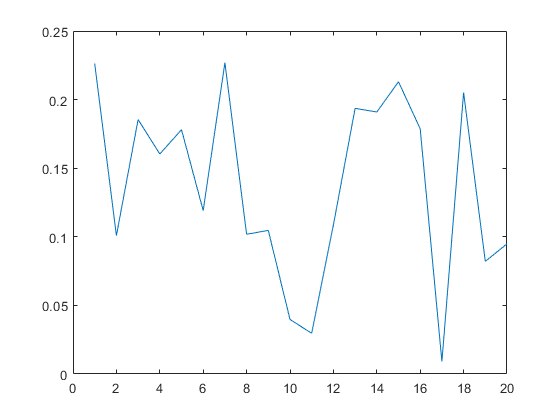


plot(res1)

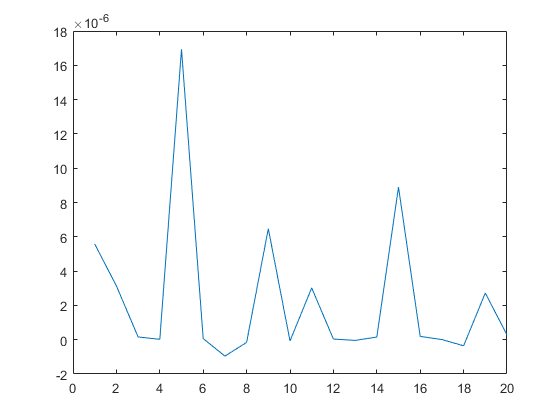

plot(res2)

table(saveR)

ans = 20×1 table
       saveR    
    ____________

    [1×9 double]
    [1×9 double]
    [1×9 double]
    [1×9 double]
    [1×9 double]
    [1×9 double]
    [1×9 double]
    [1×9 double]
    [1×9 double]
    [1×9 double]
    [1×9 double]
    [1×9 double]
    [1×9 double]
    [1×9 double]
    [1×9 double]
    [1×9 double]


trainerror = res1(end)

trainerror = 0.0949

Evaluate Train data

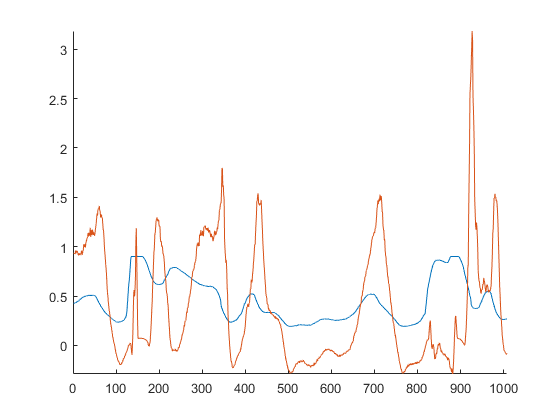


yhattrain  = evalspline(TN,featurez,n,m);

figure;
hold on
plot(zeta)
plot(yhattrain)
hold off
axis([0 inf -inf inf]);


erboiz = (yhattrain-zeta);
VAF = 1-var(erboiz)/var(zeta)

VAF = -6.6473

MSE = immse(yhattrain,zeta)

MSE = 0.3662

Evaluate Test data


yhat = evalspline(TN,tfeaturez,n,m);
erboi = (yhat-yt);
% histogram((erboi)');
VAF = 1-var(erboi)/var(yt)

VAF = -8.1424

MSE = immse(10*yhat,10*yt)

MSE = 40.8042



RMSE1 = sqrt(immse(10*yhat,10*yt))

RMSE1 = 6.3878

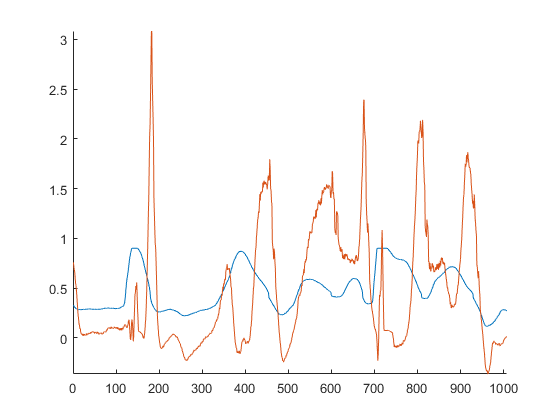


figure
hold on
plot(yt)
plot(yhat)
hold off
axis([0 inf -inf inf])

 Visualize errors

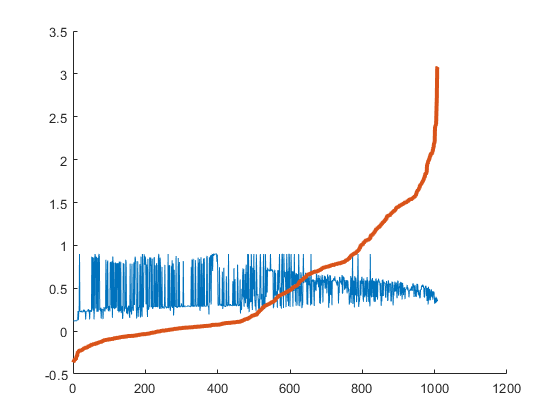

[sortout,Iss]=sort(yhat);
figure
hold on
plot(yt(Iss))
plot(sortout,'Linewidth',3)
hold off

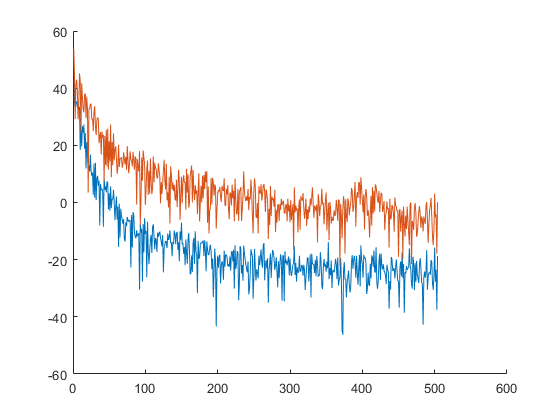


FY = mag2db(abs(fft(yhat)));
FZ = mag2db(abs(fft(yt)));

figure;
hold on
plot(FZ(1:floor(end/2)))
plot(FY(1:floor(end/2)))
hold off

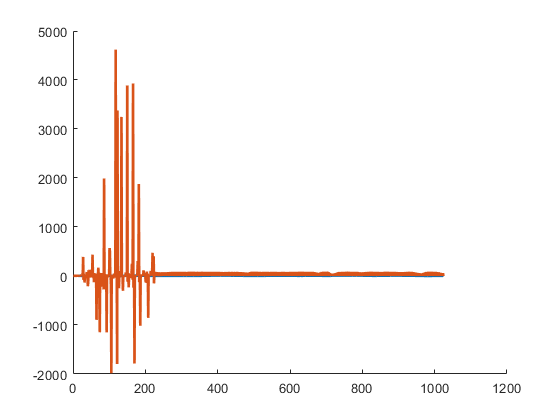


siminput = tinput;
simoutput = toutput;
numz = numel(outlags);
beginz = outlags(end)+1;
for j = beginz:1024
simfeaturez = [simoutput(j-outlags(end:-1:2))' siminput(j-inlags(1:end))'];
simfeaturez(simfeaturez<0)=0;
simfeaturez(simfeaturez>1)=1;
simoutput(j) = evalspline(TN,simfeaturez,n,m);
end

figure
hold on
plot(10*toutput+1,'linewidth',2)
plot(10*simoutput+1,'linewidth',2)
hold off


RMSE = sqrt(immse(10*toutput(beginz:end),10*simoutput(beginz:end)))

RMSE = 317.4102

toc

Elapsed time is 2.568708 seconds.


% surf(RMSE)
% xlabel('lambda * 10^-2')
% ylabel('RMSE')
% 
% zlabel('RMSE')
% plot(RMSE)
% xlabel('lambda * 10^-2')
% ylabel('RMSE')
% 
% bar(1:5,RMSE(6:10))

